# Regresión Lineal por Mínimos Cuadrados.

**Profesor: Ing. Alejandro Villicaña Paz, MTI.**

El **ajuste de curvas** consiste en encontrar una curva ***(o línea)*** que contenga una serie de puntos y que posiblemente cumpla una serie de restricciones adicionales.

El **ajuste de curvas** es un proceso mediante el cual, dado un conjunto de **N pares** de puntos **{xi, yi} **(siendo **x** la variable independiente e **y** la dependiente), se **determina una función matemática f(x)**.

### Actividad en Clase.

Con los siguientes datos de ejemplo, **grafique los puntos y el modelo de regresión lineal juntos. Calcule además, el coeficiente de correlación lineal.**

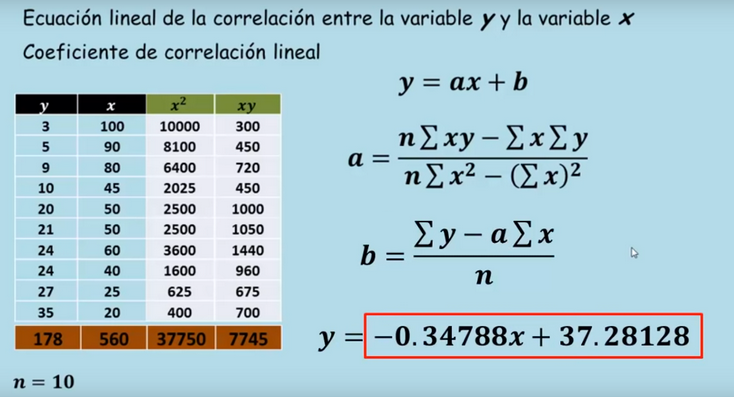

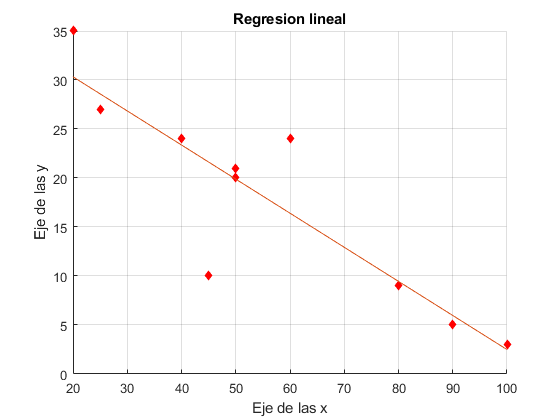

%Limpieza del espacio de trabajo.
clearvars;
clf;
% Datos experimentales ya capturados. "¡Gracias Profe!". De nada :)
x = [100,90,80,45,50,50,60,40,25,20];
y = [3,5,9,10,20,21,24,24,27,35];

% Calcular n, x^2, xy, y las sumatorias correspondientes.
n =  length(x);
x2 = x.^2;
xy = x.*y;
Sxy = sum(xy);
Sy = sum(y);
Sx = sum(x);
Sx2 = sum(x2);
% Calcular el valor para "a" y para "b".
a = (n*Sxy-Sx*Sy) / (n*Sx2-(Sx)^2);
b = (Sy-a*Sx) / (n);

% Construir la función anónima f(x) = a*x + b;
f = @(x) a*x + b;
% Ahora graficamos los puntos experimentales con la función scatter y el modelo de regresión lineal.
scatter(x,y,30,"red","filled","diamond");
hold on;
plot(x,f(x));
hold off;
grid on;
xlabel("Eje de las x");
ylabel("Eje de las y");
title("Regresion lineal");

Finalmente, realizamos el **cálculo del Coeficiente de Correlación Lineal.**

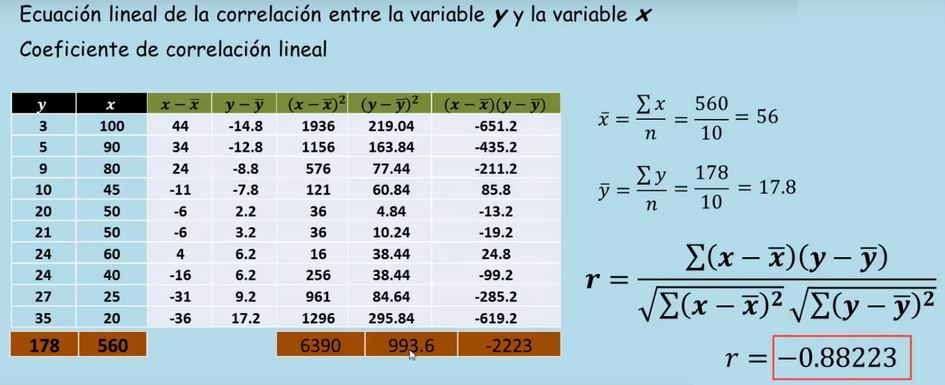

% Necesitamos calcular los promedios para "x" y para "y".
prom_x = mean(x);
prom_y = mean(y);

% Calculamos las sumatorias necesarias.
xx2 = (x- prom_x).^2;
yy2 = (y- prom_y).^2;
xxyy = (x - prom_x) .* (y - prom_y);

S_xxyy = sum(xxyy);
S_xx2 = sum(xx2);
S_yy2 = sum(yy2);

% Calculamos el valor de "r".
r = (S_xxyy)/(sqrt(S_xx2)*sqrt(S_yy2));
